clear;
n=2;
coordinate=sym("u%d",[n,1]);
X=[ cos(coordinate(2))
 sin(coordinate(2))
coordinate(1)];
uinterval=[0,10];
vinterval=[0,2*pi];
hh=differential_geometry("n",n,"coordinate",coordinate,"X",X);

hh();
hh.connection

$$\left(\begin{array}{cc} 0 & 0\\ 0 & 0 \end{array}\right)$$

$$\left(\begin{array}{cc} 0 & 0\\ 0 & 0 \end{array}\right)$$

hh.g

$$ans = \left(\begin{array}{cc} 1 & 0\\ 0 & 1 \end{array}\right)$$

hh.curvature_tensor();
hh.Scalar_curvature

$$ans = 0$$

hh.Gauss_curvature

$$ans = 0$$

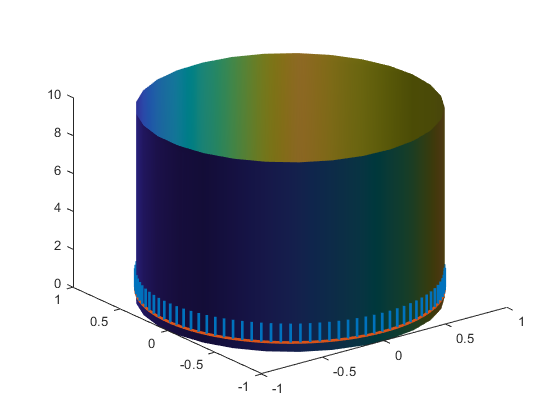

hh.drawmesh(uinterval,vinterval,0);
hold on;
syms t;
u(t)=[0.5;t];
hh.scale=0;
hh.parallel_transport(u,[0;2*pi],[1,0],100);

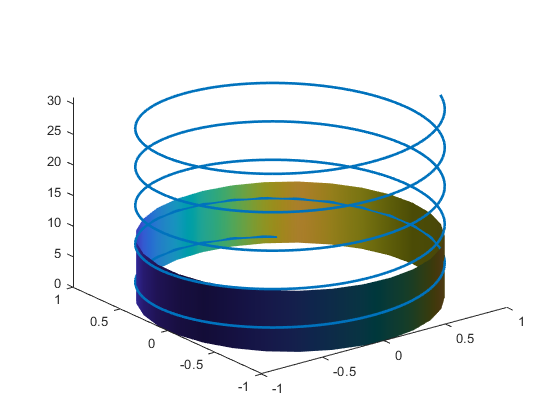

figure;
hh.drawmesh(uinterval,vinterval,0);
hold on;
hh.geodesic([0,300],[0.1, 0.1, 1, 1],500);